clc,clearvars

%option binomial pricing model

[Assetprice,Optionvalue]=binprice(30,36,4.5,1,1,0.29,1,0,0,0);

disp(Assetprice)

   30.0000   40.0928
         0   22.4479



disp(Optionvalue)

    6.9008    4.0928
         0         0




%black-scholes pricing model

[call,put]=blsprice(30,40,4.5,1,0.29,0)

call = 29.5556

put = 0


%yield is continuous compounded yield 


[call,put]=blsprice(30,40,4.5,1,0.29,0.04)

call = 28.3793

put = 0


%calculating option profits

profit=opprofit(30,40,28,1,0)

profit = 28


%optype= 0 is calls, 1 for puts
%posflag= 0 for long position, 1 for short

%SDEDDO

F = drift(0, 0.1);      % Drift rate function F(t,X)
G = diffusion(1, 0.3);  % Diffusion rate function G(t,X)

obj = sdeddo(F, G)      % dX = F(t,X)dt + G(t,X)dW

obj =    Class SDEDDO: SDE from Drift and Diffusion Objects
   --------------------------------------------------
     Dimensions: State = 1, Brownian = 1
   --------------------------------------------------
      StartTime: 0
     StartState: 1
    Correlation: 1
          Drift: drift rate function F(t,X(t)) 
      Diffusion: diffusion rate function G(t,X(t)) 
     Simulation: simulation method/function simByEuler
              A: 0
              B: 0.1
          Alpha: 1
          Sigma: 0.3


%Heston model


fs=diffusion(0.4,0.2)

fs =    Class DIFFUSION: Diffusion Rate Specification 
   --------------------------------------------- 
       Rate: diffusion rate function G(t,X(t))  
      Alpha: 0.4
      Sigma: 0.2

gs=drift(1,3)

gs =    Class DRIFT: Drift Rate Specification  
   -------------------------------------  
      Rate: drift rate function F(t,X(t)) 
         A: 1
         B: 3

o=heston(0.3:0.4:0.5,0.2,1,0.05)

o =    Class HESTON: Heston Bivariate Stochastic Volatility
   ----------------------------------------------------
     Dimensions: State = 2, Brownian = 2
   ----------------------------------------------------
      StartTime: 0
     StartState: 1 (2x1 double array) 
    Correlation: 2x2 diagonal double array 
          Drift: drift rate function F(t,X(t)) 
      Diffusion: diffusion rate function G(t,X(t)) 
     Simulation: simulation method/function simByEuler
         Return: 0.3
          Speed: 0.2
          Level: 1
     Volatility: 0.05

t=10

t = 10

s=simByEuler(o,10) %simualtion by euler

s =     1.0000    1.0000
    1.4389    0.9990
    1.7672    1.0589
    2.8515    1.0546
    5.6710    0.9360
   11.9911    0.7908
   25.0456    0.7916
   30.1619    0.9257
   52.2292    0.9517
    5.7354    0.9157


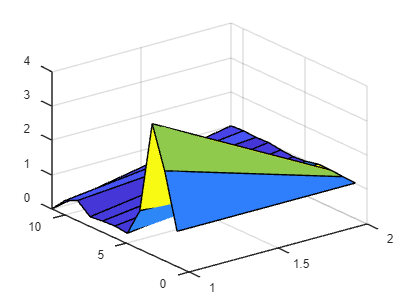



surf(s)

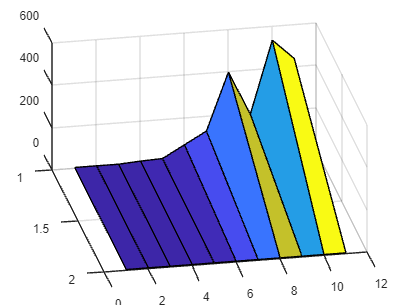


b=simByMilstein(o,10); %simulation by Milstein
surf(b)



%OPTION price simulation given 3 methods:

%MONTECARLO GBM for option pricing

S0 = 100; % Initial price of underlying asset
Sigma = .2; % Volatility of underlying asset
Strike = 110; % Strike
OptSpec = 'call'; % Call option
Settle = datetime(2013,1,1); % Settlement date of option
Maturity = datetime(2014,1,1); % Maturity date of option
r = .05; % Risk-free rate (annual, continuous compounding)
Compounding = -1; % Continuous compounding
Basis = 0; % Act/Act day count convention
T = yearfrac(Settle, Maturity, Basis); % Time to expiration in years

NTRIALS = 1000;
NPERIODS = daysact(Settle, Maturity);
dt = T/NPERIODS;
OptionGBM = gbm(r, Sigma, 'StartState', S0);
[Paths, Times, Z] = simBySolution(OptionGBM, NPERIODS, ...
'NTRIALS',NTRIALS, 'DeltaTime',dt,'Antithetic',true);

RateSpec = intenvset('ValuationDate', Settle, 'StartDates', Settle, ...
           'EndDates', Maturity, 'Rate', r, 'Compounding', Compounding, ...
           'Basis', Basis)

RateSpec = struct with fields:
           FinObj: 'RateSpec'
      Compounding: -1
             Disc: 0.9512
            Rates: 0.0500
         EndTimes: 1
       StartTimes: 0
         EndDates: 735600
       StartDates: 735235
    ValuationDate: 735235
            Basis: 0
     EndMonthRule: 1



SimulatedPrices = squeeze(Paths);
OptPrice = optpricebysim(RateSpec, SimulatedPrices, Times, OptSpec, ...
           Strike, T, 'AmericanOpt', 1)

OptPrice = 6.6206



%MONTECARLO SIMULATION OF OPTION SPREAD:

S1 = 110; % Price of first underlying asset
S2 = 100; % Price of second underlying asset
Sigma1 = .1;  % Volatility of first underlying asset
Sigma2 = .15; % Volatility of second underlying asset
Strike = 15; % Strike
Rho = .3; % Correlation between underlyings
OptSpec = 'put'; % Put option
Settle = datetime(2020,1,1); % Settlement date of option
Maturity = datetime(2023,1,1); % Maturity date of option
r = .05; % Risk-free rate (annual, continuous compounding)
Compounding = -1; % Continuous compounding
Basis = 0; % Act/Act day count convention
T = yearfrac(Settle, Maturity, Basis); % Time to expiration in years

%part 2
NTRIALS = 1000;
NPERIODS = daysact(Settle, Maturity);
dt = T/NPERIODS;
SpreadGBM = gbm(r*eye(2), diag([Sigma1;Sigma2]),'Correlation',...
[1 Rho;Rho 1],'StartState',[S1;S2]);
[Paths, Times, Z] = simBySolution(SpreadGBM, NPERIODS,'NTRIALS',NTRIALS,...
'DeltaTime',dt,'Antithetic',true);

%part3

RateSpec = intenvset('ValuationDate', Settle, 'StartDates', Settle, ...
           'EndDates', Maturity, 'Rate', r, 'Compounding', Compounding, ...
           'Basis', Basis)

RateSpec = struct with fields:
           FinObj: 'RateSpec'
      Compounding: -1
             Disc: 0.8607
            Rates: 0.0500
         EndTimes: 3
       StartTimes: 0
         EndDates: 738887
       StartDates: 737791
    ValuationDate: 737791
            Basis: 0
     EndMonthRule: 1



Spread = squeeze(Paths(:,1,:) - Paths(:,2,:));
SpreadPrice = optpricebysim(RateSpec, Spread, Times, OptSpec, Strike, ...
T, 'AmericanOpt', 1)

SpreadPrice = 13.5341


%option pricing using quasi-Euler monte carlo simulation:

heston_obj = heston (0.1, 0.2, 0.1, 0.05)  % (Return, Speed, Level, Volatility)

heston_obj =    Class HESTON: Heston Bivariate Stochastic Volatility
   ----------------------------------------------------
     Dimensions: State = 2, Brownian = 2
   ----------------------------------------------------
      StartTime: 0
     StartState: 1 (2x1 double array) 
    Correlation: 2x2 diagonal double array 
          Drift: drift rate function F(t,X(t)) 
      Diffusion: diffusion rate function G(t,X(t)) 
     Simulation: simulation method/function simByEuler
         Return: 0.1
          Speed: 0.2
          Level: 0.1
     Volatility: 0.05

[paths,time,z] = simByEuler(heston_obj,10,'ntrials',4096,'montecarlomethod','quasi','quasisequence','sobol','BrownianMotionMethod','principal-components');

%option simulation using the geometric brownian motion:

gbm_obj = gbm(0.25, 0.3)  % (B = Return, Sigma)

gbm_obj =    Class GBM: Generalized Geometric Brownian Motion
   ------------------------------------------------
     Dimensions: State = 1, Brownian = 1
   ------------------------------------------------
      StartTime: 0
     StartState: 1
    Correlation: 1
          Drift: drift rate function F(t,X(t)) 
      Diffusion: diffusion rate function G(t,X(t)) 
     Simulation: simulation method/function simByEuler
         Return: 0.25
          Sigma: 0.3

[paths,time,z] = simByEuler(gbm_obj,10,'ntrials',4096,'montecarlomethod','quasi','quasisequence','sobol','BrownianMotionMethod','brownian-bridge');




%option pricing heston model

%parameters:

AssetPrice = 80;
Rate = 0.03; %RFR
DividendYield = 0.02;
OptSpec = 'call';

V0 = 0.04;
ThetaV = 0.05;
Kappa = 1.0;
SigmaV = 0.2;
RhoSV = -0.7;


%computation for single strike

Settle = datetime(2017,6,29);
Maturity = datemnth(Settle, 6);
Strike = 80; 

Call = optByHestonNI(Rate, AssetPrice, Settle, Maturity, OptSpec, Strike, ...
    V0, ThetaV, Kappa, SigmaV, RhoSV, 'DividendYield', DividendYield)

%computation for vector of strikes (different strikes dimentions)

Settle = datetime(2017,6,29);
Maturity = datemnth(Settle, 6);
Strike = (76:2:84)';

Call = optByHestonNI(Rate, AssetPrice, Settle, Maturity, OptSpec, Strike, ...
    V0, ThetaV, Kappa, SigmaV, RhoSV, 'DividendYield', DividendYield)

%computation for vectors of strikes, vector of dates of same length

Settle = datetime(2017,6,29);
Maturity = datemnth(Settle, [12 18 24 30 36]); % Five maturities
Strike = [76 78 80 82 84]'; % Five strikes

Call = optByHestonNI(Rate, AssetPrice, Settle, Maturity, OptSpec, Strike, ...
    V0, ThetaV, Kappa, SigmaV, RhoSV, 'DividendYield', DividendYield)

%surface expansion

Call = optByHestonNI(Rate, AssetPrice, Settle, Maturity, OptSpec, Strike, ...
    V0, ThetaV, Kappa, SigmaV, RhoSV, 'DividendYield', DividendYield, ...
    'ExpandOutput', true) % (5 x 5) matrix output

%PLOTING MULTIVARIATE FUNCTION

Settle = datetime(2017,6,29);
Maturity = datemnth(Settle, 12*[1/12 0.25 (0.5:0.5:3)]');
Times = yearfrac(Settle, Maturity);
Strike = (2:2:200)';

Call = optByHestonNI(Rate, AssetPrice, Settle, Maturity, OptSpec, Strike, ...
    V0, ThetaV, Kappa, SigmaV, RhoSV, 'DividendYield', DividendYield, ...
    'ExpandOutput', true);

[X,Y] = meshgrid(Times,Strike);

figure;
surf(X,Y,Call);
title('Price');
xlabel('Years to Option Expiry');
ylabel('Strike');
view(-112,34);
xlim([0 Times(end)]);
zlim([0 80]);


